# **Analyzing Neural Time Series Data**

*Theory and Practice: Mike X Cohen*

*Presented by: Armin Toghi*

*IDS Executive Member of Signal and Neuroimaging Department*

[armintoghi85@gmail.com](http://armintoghi85@gmail.com)

### Connectivity Methods:

### Phase-based Connectivity

### Approach 1: intersite phase clustering (ISPC) 

There are several terms that are used in the literature to describe phase-based connectivity, including phase-locking value/statistic/factor, phase synchronization, and phase coherence. Arguably, these are suboptimal terms, partly because they are interpretations of results rather than descriptions of methods.

Here, the term intersite phase clustering (ISPC) is preferred. ISPC is a concise description of the method (clustering in polar space of phase angle differences between electrodes, voxels, or neurons) without any assumptions or interpretations regarding putative neurophysiological mechanisms being made.  

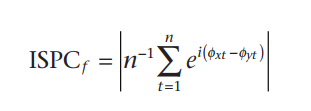

% load sample EEG dataset
load sampleEEGdata

% names of the channels you want to synchronize
channel1 = 'p1';
channel2 = 'pz';

% create complex Morlet wavelet
center_freq = 5; % in Hz
time        = -1:1/EEG.srate:1; % time for wavelet
wavelet     = exp(2*1i*pi*center_freq.*time) .* exp(-time.^2./(2*(4/(2*pi*center_freq))^2))/center_freq;
half_of_wavelet_size = (length(time)-1)/2;

% FFT parameters
n_wavelet     = length(time);
n_data        = EEG.pnts;
n_convolution = n_wavelet+n_data-1;

% FFT of wavelet
fft_wavelet = fft(wavelet,n_convolution);

% initialize output time-frequency data
phase_data = zeros(2,EEG.pnts);
real_data  = zeros(2,EEG.pnts);

% find channel indices
chanidx = zeros(1,2); % always initialize!
chanidx(1) = find(strcmpi(channel1,{EEG.chanlocs.labels}));
chanidx(2) = find(strcmpi(channel2,{EEG.chanlocs.labels}));


% run convolution and extract filtered signal (real part) and phase
for chani=1:2
    fft_data = fft(squeeze(EEG.data(chanidx(chani),:,1)),n_convolution);
    convolution_result_fft = ifft(fft_wavelet.*fft_data,n_convolution) * sqrt(4/(2*pi*center_freq));
    convolution_result_fft = convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size);
 
    % collect real and phase data
    phase_data(chani,:) = angle(convolution_result_fft);
    real_data(chani,:)  = real(convolution_result_fft);
end


% open and name figure
%figure, set(gcf,'Name','Movie magic minimizes the mystery.','Number','off');

% draw the filtered signals
subplot(321)
filterplotH1 = plot(EEG.times(1),real_data(1,1),'b');
hold on
filterplotH2 = plot(EEG.times(1),real_data(2,1),'m');
set(gca,'xlim',[EEG.times(1) EEG.times(end)],'ylim',[min(real_data(:)) max(real_data(:))])
xlabel('Time (ms)')
ylabel('Voltage (\muV)')
title([ 'Filtered signal at ' num2str(center_freq) ' Hz' ])

% draw the phase angle time series
subplot(322)
phaseanglesH1 = plot(EEG.times(1),phase_data(1,1),'b');
hold on
phaseanglesH2 = plot(EEG.times(1),phase_data(2,1),'m');
set(gca,'xlim',[EEG.times(1) EEG.times(end)],'ylim',[-pi pi]*1.1,'ytick',-pi:pi/2:pi)
xlabel('Time (ms)')
ylabel('Phase angle (radian)')
title('Phase angle time series')

% draw phase angle differences in cartesian space
subplot(323)
filterplotDiffH1 = plot(EEG.times(1),real_data(1,1)-real_data(2,1),'b');
set(gca,'xlim',[EEG.times(1) EEG.times(end)],'ylim',[-10 10])
xlabel('Time (ms)')
ylabel('Voltage (\muV)')
title([ 'Filtered signal at ' num2str(center_freq) ' Hz' ])

% draw the phase angle time series
subplot(324)
phaseanglesDiffH1 = plot(EEG.times(1),phase_data(1,1)-phase_data(2,1),'b');
set(gca,'xlim',[EEG.times(1) EEG.times(end)],'ylim',[-pi pi]*2.2,'ytick',-2*pi:pi/2:pi*2)
xlabel('Time (ms)')
ylabel('Phase angle (radian)')
title('Phase angle time series')

% draw phase angles in polar space
subplot(325)
polar2chanH1 = polar([phase_data(1,1) phase_data(1,1)]',repmat([0 1],1,1)','b');
hold on
polar2chanH2 = polar([phase_data(1,1) phase_data(2,1)]',repmat([0 1],1,1)','m');
title('Phase angles from two channels')
 
% draw phase angle differences in polar space
subplot(326)
polarAngleDiffH = polar([zeros(1,1) phase_data(2,1)-phase_data(1,1)]',repmat([0 1],1,1)','k');
title('Phase angle differences from two channels')
 
% now update plots at each timestep
% Note: in/decrease skipping by 10 to speed up/down the movie
for ti=1:10:EEG.pnts
    
    % update filtered signals
    set(filterplotH1,'XData',EEG.times(1:ti),'YData',real_data(1,1:ti))
    set(filterplotH2,'XData',EEG.times(1:ti),'YData',real_data(2,1:ti))
    
    % update cartesian plot of phase angles
    set(phaseanglesH1,'XData',EEG.times(1:ti),'YData',phase_data(1,1:ti))
    set(phaseanglesH2,'XData',EEG.times(1:ti),'YData',phase_data(2,1:ti))
    
    % update cartesian plot of phase angles differences
    set(phaseanglesDiffH1,'XData',EEG.times(1:ti),'YData',phase_data(1,1:ti)-phase_data(2,1:ti))
    set(filterplotDiffH1,'XData',EEG.times(1:ti),'YData',real_data(1,1:ti)-real_data(2,1:ti))
    
    subplot(325)
    cla
    polar(repmat(phase_data(1,1:ti),1,2)',repmat([0 1],1,ti)','b');
    hold on
    polar(repmat(phase_data(2,1:ti),1,2)',repmat([0 1],1,ti)','m');
    
    subplot(326)
    cla
    polar(repmat(phase_data(2,1:ti)-phase_data(1,1:ti),1,2)',repmat([0 1],1,ti)','k');
    
    drawnow
end

- ISPC (along with many other phase-based connectivity measures) is symmetric (that is, nondirectional)  

- Figure shows that the actual phase lag between electrodes does not matter. What matters is that the phase lag is consistent across time.  

###  ***ISPC-time***

ISPC was computed over a window of time from one trial. It is likely that you will want to examine changes in ISPC over time.  

Compute ISPC in sliding time segments, analogous to the way the FFT was computed in sliding time segments in the short-time FFT method (chapter 15). After ISPC has been computed in sliding time segments within a trial, the ISPC would be computed for each trial, and then the results can be averaged across trials (or correlated with a trial-varying behavior or experiment parameter; more on this later). Hereafter, this approach is called *ISPC-time*.  

### ***ISPC-Trials***  

ISPC over trials (hereafter called *ISPC-trials*; the term “ ISPC ” is used when discussing both ISPC-time and ISPC-trials) is a similar but alternative method for assessing task-related phase-based connectivity. 

With ISPCtrials, the distribution of phase angle differences is generated at each time point over trials, whereas with ISPC-time, that distribution is computed at each trial over time points.

ISPC-trials add a stronger constraint, which is that phase angle differences must be consistent over trials.   

% note: see commented line "time_window_idx..." below for panels C and D

channel1 = 'fz';
channel2 = 'o1';

freqs2use  = logspace(log10(4),log10(30),15); % 4-30 Hz in 15 steps
times2save = -400:20:800;
timewindow = linspace(1.5,3,length(freqs2use)); % number of cycles on either end of the center point (1.5 means a total of 3 cycles))
baselinetm = [-400 -200];

% wavelet and FFT parameters
time          = -1:1/EEG.srate:1;
half_wavelet  = (length(time)-1)/2;
num_cycles    = logspace(log10(4),log10(8),length(freqs2use));
n_wavelet     = length(time);
n_data        = EEG.pnts*EEG.trials;
n_convolution = n_wavelet+n_data-1;

% time in indices
times2saveidx = dsearchn(EEG.times',times2save');
baselineidx   = dsearchn(times2save',baselinetm');

chanidx    = zeros(1,2); % always initialize!
chanidx(1) = find(strcmpi(channel1,{EEG.chanlocs.labels}));
chanidx(2) = find(strcmpi(channel2,{EEG.chanlocs.labels}));

% initialize
ispc = zeros(length(freqs2use),length(times2save));
ps   = zeros(length(freqs2use),length(times2save));

% data FFTs
data_fft1 = fft(reshape(EEG.data(chanidx(1),:,:),1,n_data),n_convolution);
data_fft2 = fft(reshape(EEG.data(chanidx(2),:,:),1,n_data),n_convolution);


for fi=1:length(freqs2use)
    
    % create wavelet and take FFT
    s = num_cycles(fi)/(2*pi*freqs2use(fi));
    wavelet_fft = fft( exp(2*1i*pi*freqs2use(fi).*time) .* exp(-time.^2./(2*(s^2))) ,n_convolution);
    
    % phase angles from channel 1 via convolution
    convolution_result_fft = ifft(wavelet_fft.*data_fft1,n_convolution);
    convolution_result_fft = convolution_result_fft(half_wavelet+1:end-half_wavelet);
    phase_sig1 = angle(reshape(convolution_result_fft,EEG.pnts,EEG.trials));
    
    % phase angles from channel 2 via convolution
    convolution_result_fft = ifft(wavelet_fft.*data_fft2,n_convolution);
    convolution_result_fft = convolution_result_fft(half_wavelet+1:end-half_wavelet);
    phase_sig2 = angle(reshape(convolution_result_fft,EEG.pnts,EEG.trials));
    
    % phase angle differences
    phase_diffs = phase_sig1-phase_sig2;
    
    % compute ICPS over time
    ps(fi,:) = abs(mean(exp(1i*phase_diffs(times2saveidx,:)),2));
    
    % compute time window in indices for this frequency
    time_window_idx = round((1000/freqs2use(fi))*timewindow(fi)/(1000/EEG.srate));
%     time_window_idx = round(300/(1000/EEG.srate)); % set 300 to 100 for figure 3c/d
    
    for ti=1:length(times2save)
        
        % compute phase synchronization
        phasesynch = abs(mean(exp(1i*phase_diffs(times2saveidx(ti)-time_window_idx:times2saveidx(ti)+time_window_idx,:)),1));
        
        % average over trials
        ispc(fi,ti) = mean(phasesynch);
    end
end % end frequency loop

figure
% ISPC strength from a pretrial baseline period of –400 to –200 ms was subtracted to highlight
%task-related effects.
contourf(times2save,freqs2use,ispc-repmat(mean(ispc(:,baselineidx(1):baselineidx(2)),2),1,size(ispc,2)),20,'linecolor','none')
set(gca,'clim',[-.08 .08],'yscale','log','ytick',round(logspace(log10(freqs2use(1)),log10(freqs2use(end)),8)))
xlabel('Time (ms)'), ylabel('Frequency (Hz)')

figure
plot(freqs2use,(1000./freqs2use).*timewindow*2,'o-','markerface','k')
hold on
plot(freqs2use,(1000./freqs2use).*timewindow(1)*2,'ro-','markerface','m')
ylabel('Window width (ms)'), xlabel('Frequency (Hz)')
legend({'variable windows';'fixed 3*f window'})

figure
contourf(times2save,freqs2use,bsxfun(@minus,ps,mean(ps(:,baselineidx(1):baselineidx(2)),2)),20,'linecolor','none')
set(gca,'clim',[-.2 .2],'yscale','log','ytick',round(logspace(log10(freqs2use(1)),log10(freqs2use(end)),8)),'xlim',[-300 800])
xlabel('Time (ms)'), ylabel('Frequency (Hz)')

### 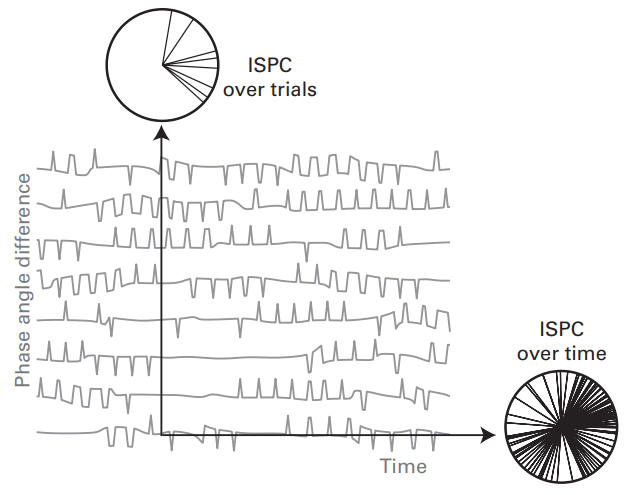

**Should you compute ISPC-time or ISPC-trials?**

**ISPC-time Adv**

First, it is less sensitive to trial-to-trial jitter of experiment event timing (see figure 19.9) because even if the event timing is jittered, the timing of activity at different EEG electrodes will never be jittered relative to the timing of activity at other electrodes. 

Second, ISPC-time is insensitive to phase angle differences being different on different trials and can therefore be conceptualized as measuring total (non-phase-locked and phase-locked) rather than only phase-locked connectivity.  

For both of these reasons, ISPC-time is better suited for detecting high-frequency connectivity. The disadvantage of ISPC-time is that it requires longer withintrial time segments.   

Good for resting state or long tasks.

Can be used for tasks over sliding window (better for higher frequencies)

**ISPC-trial Adv**

Good for standard trial-based tasks

Can fail to detect real synchrony if phase angles differ across trials

### Approach 2: **Spectral Coherence (Magnitude-Squared Coherence)**  

Spectral coherence is similar to ISPC, but the phase values are weighted by power values.  Because spectral coherence also incorporates power information, results from spectral coherence are likely to be influenced by strong increases or decreases in power.  If connectivity increases but power simultaneously decreases, spectral coherence may provide biased results (Lachaux et al. 1999)  

*m x *and *m y *are the analytic signals X and Y (the vertical bars surrounding them indicate to take the magnitude of the analytic signals, e.g., via the Matlab function abs), ϕ*xy *is the phase angle difference between electrodes X and Y, and *t *refers to trials or time points, depending on whether coherence is computed over time or over trials.   

You might notice that a problem with equation 26.3 is that the result scales with power, and power changes over frequency, time, task events, and so on. This is why spectral coherence is then normalized by power, by treating equation 26.3 as the numerator and the combined power as the denominator.

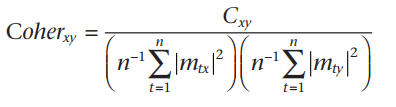

% select channels
channel1 = 'fz';
channel2 = 'o1';

freqs2use  = logspace(log10(4),log10(30),15); % 4-30 Hz in 15 steps
times2save = -400:20:800;



% wavelet and FFT parameters

time          = -1:1/EEG.srate:1;
half_wavelet  = (length(time)-1)/2;
n_wavelet     = length(time);
n_data        = EEG.pnts*EEG.trials;
n_convolution = n_wavelet+n_data-1;
num_cycles    = logspace(log10(4),log10(8),length(freqs2use));
chanidx    = zeros(1,2); % always initialize!
chanidx(1) = find(strcmpi(channel1,{EEG.chanlocs.labels}));
chanidx(2) = find(strcmpi(channel2,{EEG.chanlocs.labels}));

% data FFTs
data_fft1 = fft(reshape(EEG.data(chanidx(1),:,:),1,n_data),n_convolution);
data_fft2 = fft(reshape(EEG.data(chanidx(2),:,:),1,n_data),n_convolution);

% time in indices
baselinetm = [-400 -200];
times2saveidx = dsearchn(EEG.times',times2save');
baselineidx   = dsearchn(times2save',baselinetm');

% initialize
spectcoher = zeros(length(freqs2use),length(times2save));

for fi=1:length(freqs2use)
    
    % create wavelet and take FFT
    s = num_cycles(fi)/(2*pi*freqs2use(fi));
    wavelet_fft = fft( exp(2*1i*pi*freqs2use(fi).*time) .* exp(-time.^2./(2*(s^2))) ,n_convolution);
    
    % phase angles from channel 1 via convolution
    convolution_result_fft = ifft(wavelet_fft.*data_fft1,n_convolution);
    convolution_result_fft = convolution_result_fft(half_wavelet+1:end-half_wavelet);
    sig1 = reshape(convolution_result_fft,EEG.pnts,EEG.trials);
    
    % phase angles from channel 2 via convolution
    convolution_result_fft = ifft(wavelet_fft.*data_fft2,n_convolution);
    convolution_result_fft = convolution_result_fft(half_wavelet+1:end-half_wavelet);
    sig2 = reshape(convolution_result_fft,EEG.pnts,EEG.trials);
    
    % compute power and cross-spectral power
    spec1 = mean(sig1.*conj(sig1),2); % same as abs(sig1).^2
    spec2 = mean(sig2.*conj(sig2),2);
    specX = abs(mean(sig1.*conj(sig2),2)).^2;
    
    % alternative notation for the same procedure, using the Euler-like expression: Me^ik
    %spec1 = mean(abs(sig1).^2,2);
    %spec2 = mean(abs(sig2).^2,2);
    %specX = abs(mean( abs(sig1).*abs(sig2) .* exp(1i*(angle(sig1)-angle(sig2))) ,2)).^2;
    
    % compute spectral coherence, using only requested time points
    spectcoher(fi,:) = specX(times2saveidx)./(spec1(times2saveidx).*spec2(times2saveidx));
    
    % yet another equivalent notation, just FYI
    %spec1 = sum(sig1.*conj(sig1),2);
    %spec2 = sum(sig2.*conj(sig2),2);
    %specX = sum(sig1.*conj(sig2),2);
    %spectcoher(fi,:) = abs(specX(times2saveidx)./sqrt(spec1(times2saveidx).*spec2(times2saveidx))).^2;
    
    
    % imaginary coherence
    %spec1 = sum(sig1.*conj(sig1),2);
    %spec2 = sum(sig2.*conj(sig2),2);
    %specX = sum(sig1.*conj(sig2),2);
    % spectcoher(fi,:) = abs(imag(specX(times2saveidx)./sqrt(spec1(times2saveidx).*spec2(times2saveidx))));
end


figure
subplot(121)
contourf(times2save,freqs2use,spectcoher,20,'linecolor','none') % 
set(gca,'clim',[0 .2],'yscale','log','ytick',round(logspace(log10(freqs2use(1)),log10(freqs2use(end)),8)),'xlim',[times2save(1) times2save(end)])
title('"Raw" spectral coherence')

subplot(122)
contourf(times2save,freqs2use,spectcoher-repmat(mean(spectcoher(:,baselineidx(1):baselineidx(2)),2),1,size(spectcoher,2)),20,'linecolor','none') % 
set(gca,'clim',[-.1 .1],'yscale','log','ytick',round(logspace(log10(freqs2use(1)),log10(freqs2use(end)),8)),'xlim',[times2save(1) times2save(end)])
xlabel('Time (ms)'), ylabel('Frequency (Hz)')
title('Baseline-subtracted spectral coherence')

### 3. **Phase Lag-Based Measures**  

### **Which Measure of Phase Connectivity Should You Use?**  

Depends on whether you are designing exploratory or hypothese-based study?

- If you have a priori hypotheses about a small number of specific connectivity patterns, ISPC combined with tests against volume conduction might be a better option because ISPC is maximally sensitive to detecting connectivity, regardless of the phase angle differences  

- On the other hand, if you have no or few hypotheses and will thus do a lot of data exploration by testing for connectivity over many electrode pairs, time points, and frequency bands, it might be better to use a connectivity measure that is insensitive to volume conduction, even at the risk of ignoring some potentially true connectivity patterns, because inspecting each of hundreds or thousands of results for possible contamination by volume conduction is impractical.  

Another consideration is whether to compute connectivity over trials or over time. This decision is less influenced by your orientation toward hypothesis testing versus data exploration but rather depends on your task design and expectations about the results. Differences between connectivity over trials versus over time are discussed in section 26.3, but briefly: connectivity over time is more sensitive to detecting high-frequency connectivity and for resting-state data or tasks that have long event durations (i.e., at least several hundred milliseconds) due to the poor temporal precision of connectivity over time; connectivity over trials has higher temporal precision and is therefore better able to identify the time course of changes in connectivity and is also better able to identify transient changes in connectivity.  

### Exercise

Select one seed electrode and one frequency band and compute phase-based connectivity between that seed electrode and every other electrode. Use two methods for phase-based connectivity that were presented in this chapter, one that is volume conduction independent (e.g., PLI) and one that could produce spurious connectivity due to volume conduction (e.g., ISPC). Do not apply a baseline subtraction. Make topographical plots of seeded connectivity in a time window of your choice (e.g., 300–350 ms). What are the similarities and differences between results from the two methods, and what might be the reasons for the similarities and differences?  